# Diffusion

## Introduction

This code solve the simple first order (1D) linear ODE

        $\frac{dx}{dt} =\dot{x}=\eta(t)$      where eta is Gaussian white noise

Parmeters

t = 1:1:1000;                    %time
v=randn(length(t),1000);         %random velocities(#time points per trace, #traces)
v(1,10)

ans = -0.7619

x=cumsum(v);                    %integrate by summing the random velocities to give position
                                %(#time points per trace, #traces)
% x=x+10*randn(length(t),1000);  %add measurement noise to x

## Plot the velocities  

f = figure;
a1 = subplot(2,1,1); hold on; % upper panel = v(t)
set(gca,'xlim',[0 1000],'ylim',[-5 5]);
plot(t,v(:,1),'k-');                    % plot dx/dt vs time for the first trace only
xlabel('time');
ylabel('dx/dt');

## Plot the integrated positions  

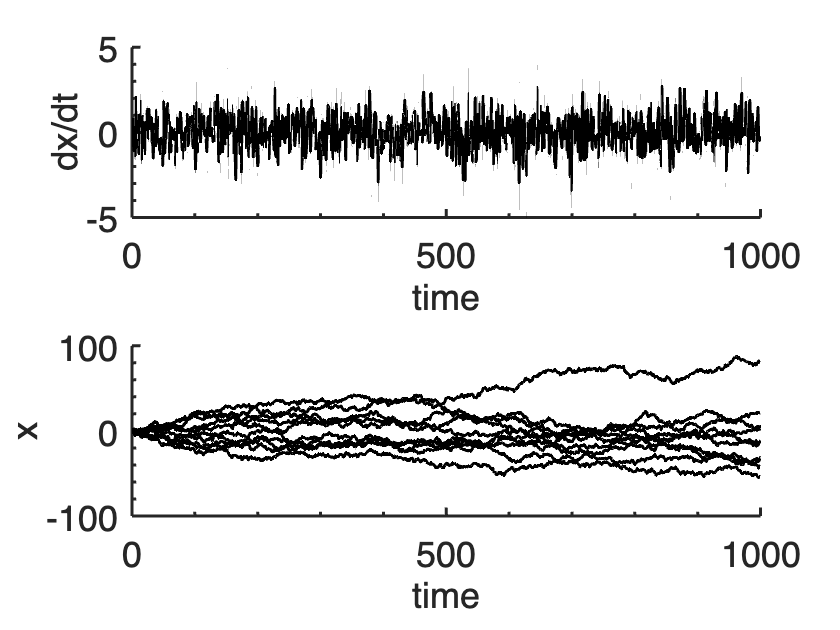


a2 = subplot(2,1,2); hold on; %lower panel = x(t)
set(gca,'xlim',[0 1000],'ylim',[-100 100]);
plot(t,x(:,[1:1:10]),'k-');                    % plot the first 10 trajectories
xlabel('time');
ylabel('x');
PrettyFig;                                      %makes the labels and curves prettier

## Plot the histogram of velocities  

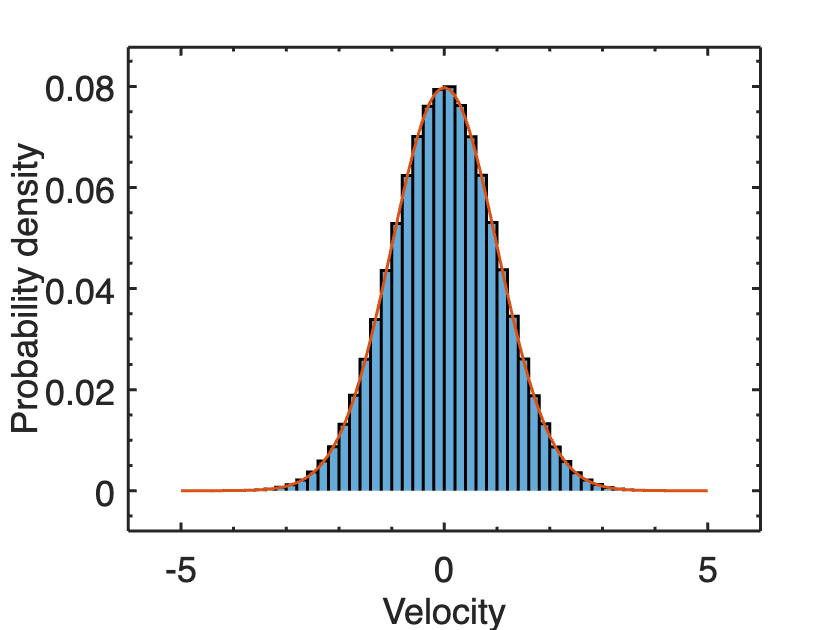

figure;
h=histogram(v);
h.Normalization = 'probability';            %plot as a probability distribition
h.BinWidth = .2;
hold on;

%fit to a Gaussian
y = -5:0.1:5;
mu = 0;
sigma = 1;
f = h.BinWidth*exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));       %note normalization by BinWidth
plot(y,f,'LineWidth',2);
xlabel('Velocity');
ylabel('Probability density');
PrettyFig;

## Plot the histogram of positions are various times  

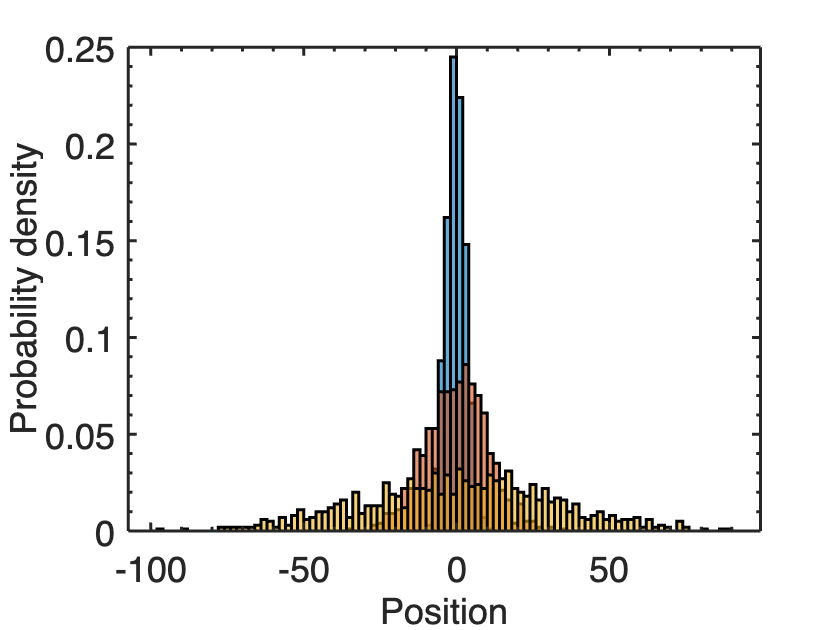

figure;
%h0=histogram(x(1,:));
%hold on;
h1=histogram(x(10,:));              %positions at t=10
hold on;
h2=histogram(x(100,:));             %positions at t=100
hold on;
h3=histogram(x(1000,:));               %positions at t=1000
%h0.Normalization = 'probability';
%h0.BinWidth = 2;
h1.Normalization = 'probability';
h1.BinWidth = 2;
h2.Normalization = 'probability';
h2.BinWidth = 2;
h3.Normalization = 'probability';
h3.BinWidth = 2;
xlabel('Position');
ylabel('Probability density');
PrettyFig;                      %makes the labels and curves prettier

## Mean-square displacement  

VarX=var(x.');                   %Variance at each time point (note taking transpose of matrx)
VarX(1,10),VarX(1,100),VarX(1,1000)

ans = 10.3984

ans = 99.9587

ans = 954.7301

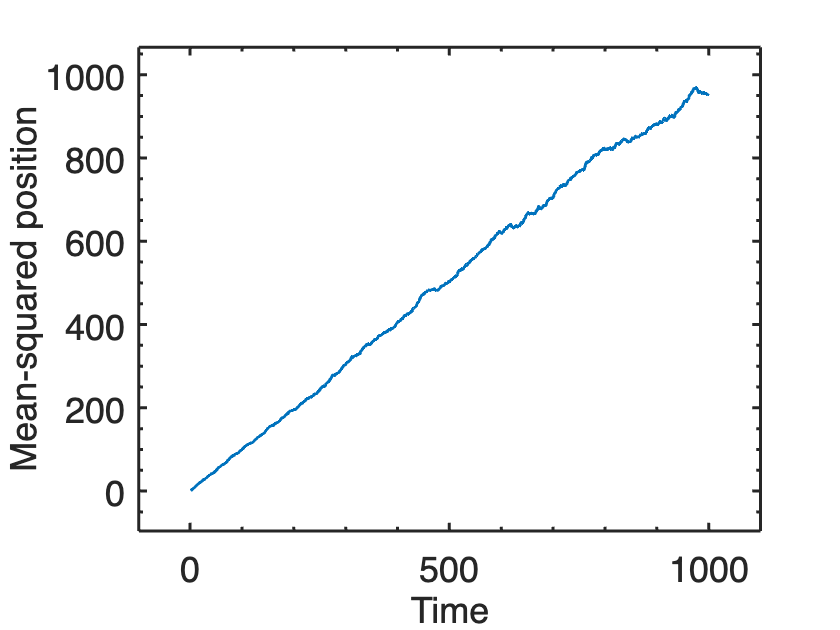

figure;
plot(t,VarX(1,:),'LineWidth',2);         
xlabel('Time');
ylabel('Mean-squared position');
PrettyFig;

## Question 1.

MSD = 2Dt

The plot, in theory, is linear in time -- it shows slight variations above, of course.

Considering time interval from *t = 0 to 1000s*,

    *delta(MSD) = 2D*delta(t)*

*    (1000-0) = 2D*(1000-0)*

So, the **diffusion coefficient is D = 0.5**.

## Question 2: Double the noise.

t = 1:1:1000;                    %time
v=2*randn(length(t),1000);         %random velocities(#time points per trace, #traces)
v(1,10)

ans = -2.3402

x=cumsum(v);                    %integrate by summing the random velocities to give position
% x=x+20*randn(length(t),1000);

## Velocities

f = figure;
a1 = subplot(2,1,1); hold on; % upper panel = v(t)
set(gca,'xlim',[0 1000],'ylim',[-5 5]);
plot(t,v(:,1),'k-');                    % plot dx/dt vs time for the first trace only
xlabel('time');
ylabel('dx/dt');

## Integrated positions

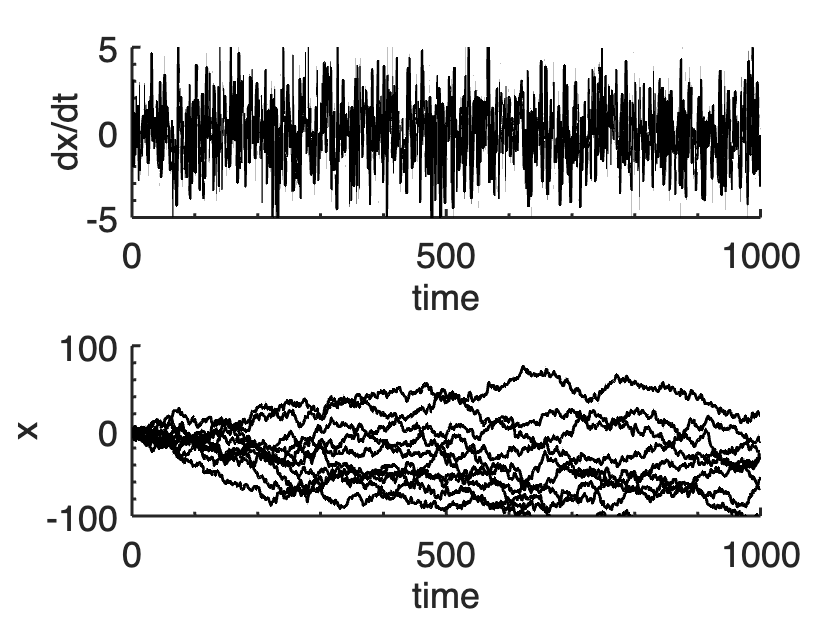

a2 = subplot(2,1,2); hold on; %lower panel = x(t)
set(gca,'xlim',[0 1000],'ylim',[-100 100]);
plot(t,x(:,[1:1:10]),'k-');                    % plot the first 10 trajectories
xlabel('time');
ylabel('x');
PrettyFig;

## Velocity histograms

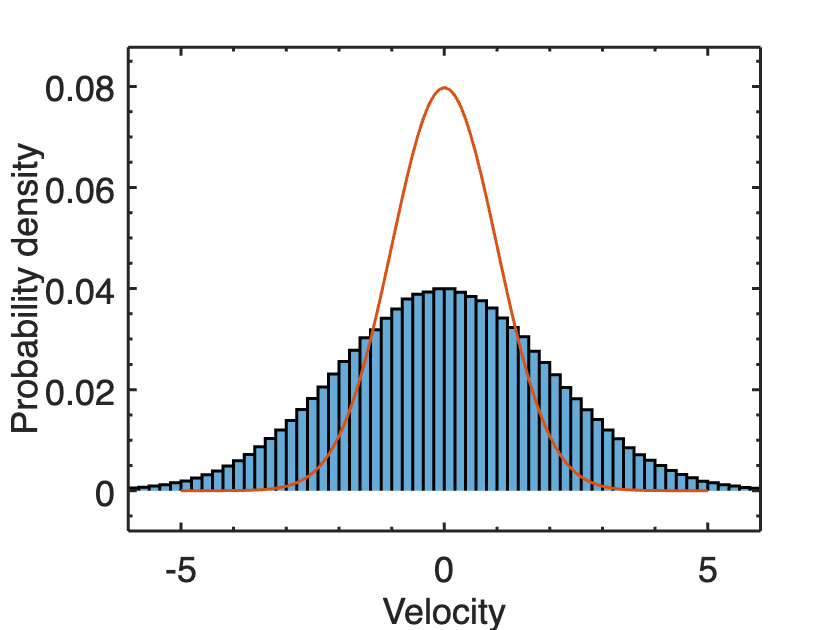

figure;
h=histogram(v);
h.Normalization = 'probability';            %plot as a probability distribition
h.BinWidth = .2;
hold on;

%fit to a Gaussian
y = -5:0.1:5;
mu = 0;
sigma = 1;
f = h.BinWidth*exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));       %note normalization by BinWidth
plot(y,f,'LineWidth',2);
xlabel('Velocity');
ylabel('Probability density');
PrettyFig;

## Position histograms

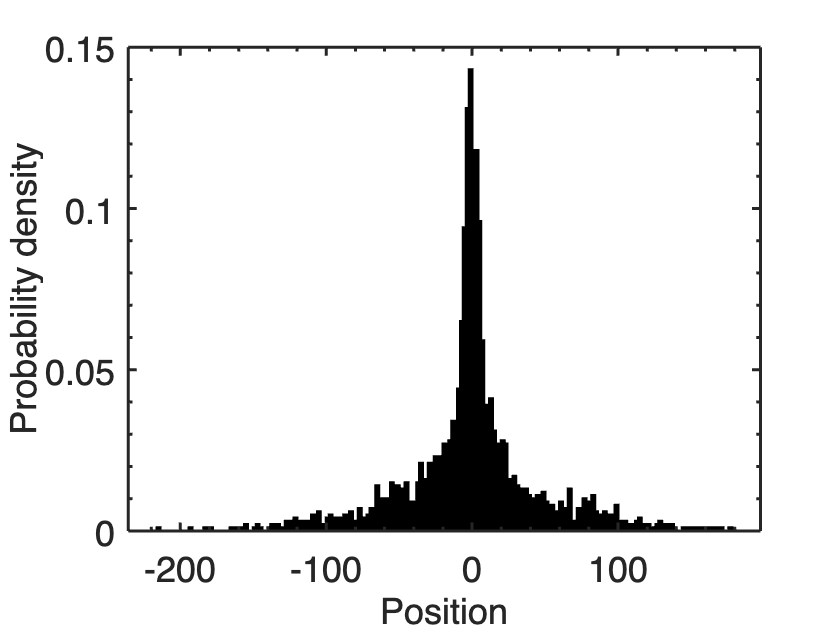

figure;
%h0=histogram(x(1,:));
%hold on;
h1=histogram(x(10,:));              %positions at t=10
hold on;
h2=histogram(x(100,:));             %positions at t=100
hold on;
h3=histogram(x(1000,:));               %positions at t=1000
%h0.Normalization = 'probability';
%h0.BinWidth = 2;
h1.Normalization = 'probability';
h1.BinWidth = 2;
h2.Normalization = 'probability';
h2.BinWidth = 2;
h3.Normalization = 'probability';
h3.BinWidth = 2;
xlabel('Position');
ylabel('Probability density');
PrettyFig; 

## MSD plots

VarX=var(x.');                   %Variance at each time point (note taking transpose of matrx)
VarX(1,10),VarX(1,100),VarX(1,1000)

ans = 38.4191

ans = 404.3587

ans = 4.0460e+03

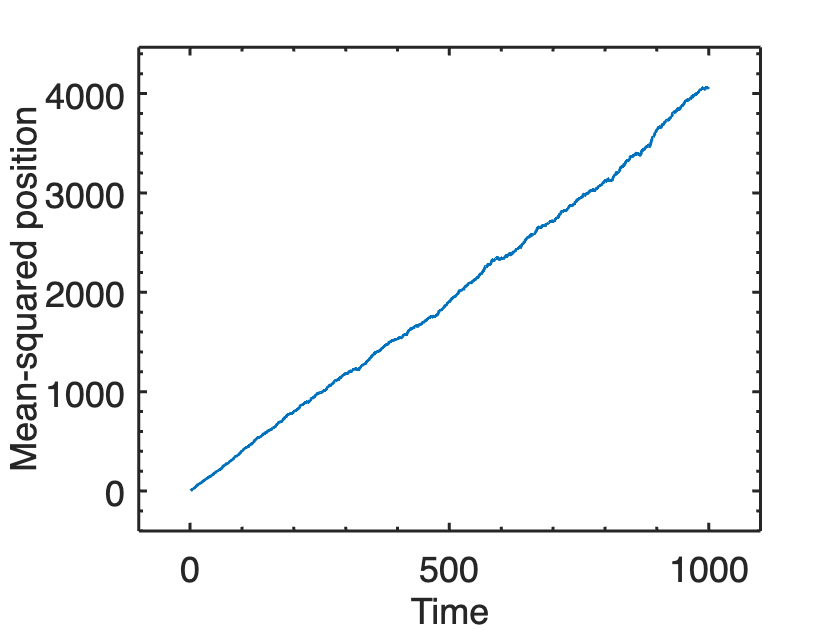

figure;
plot(t,VarX(1,:),'LineWidth',2);         
xlabel('Time');
ylabel('Mean-squared position');
PrettyFig;

**Doubled noise**.

*    delta(MSD) = 2D*delta(t)*

*    (4000-0) = 2D*(1000-0)*

So, the **diffusion coefficient is D = ~2**.

## Question 3.

n_traces = 10;
t = 1:1:1000;                    %time
v=randn(length(t), n_traces);         %random velocities(#time points per trace, #traces)
x=cumsum(v);                    %integrate by summing the random velocities to give position
% x=x+5*randn(length(t), n_traces);

## Position histograms

figure;
%h0=histogram(x(1,:));
%hold on;
h1=histogram(x(10,:));              %positions at t=10
hold on;
h2=histogram(x(100,:));             %positions at t=100
hold on;
h3=histogram(x(1000,:));               %positions at t=1000
%h0.Normalization = 'probability';
%h0.BinWidth = 2;
h1.Normalization = 'probability';
h1.BinWidth = 2;
h2.Normalization = 'probability';
h2.BinWidth = 2;
h3.Normalization = 'probability';
h3.BinWidth = 2;
xlabel('Position');
ylabel('Probability density');
PrettyFig; 

## MSD plots

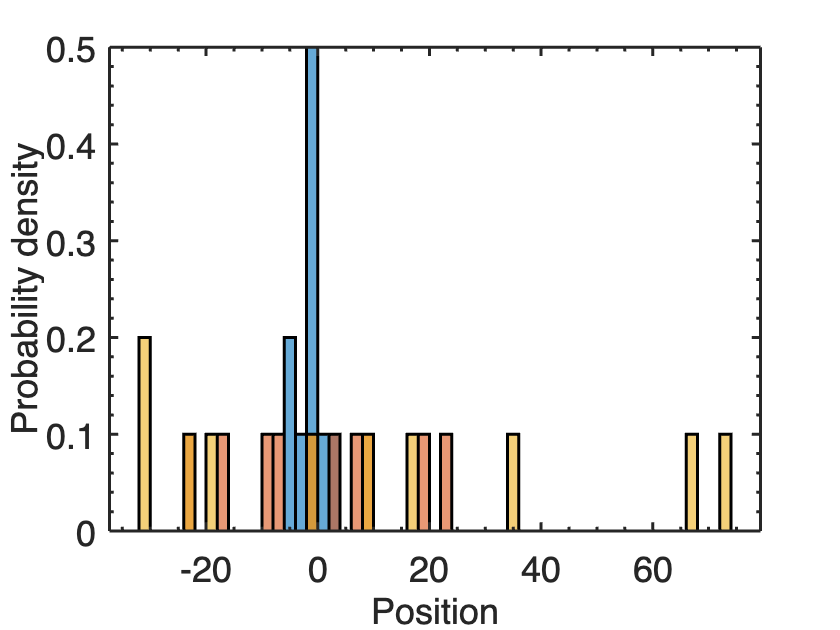

VarX=var(x.');                   %Variance at each time point (note taking transpose of matrx)
PrettyFig;

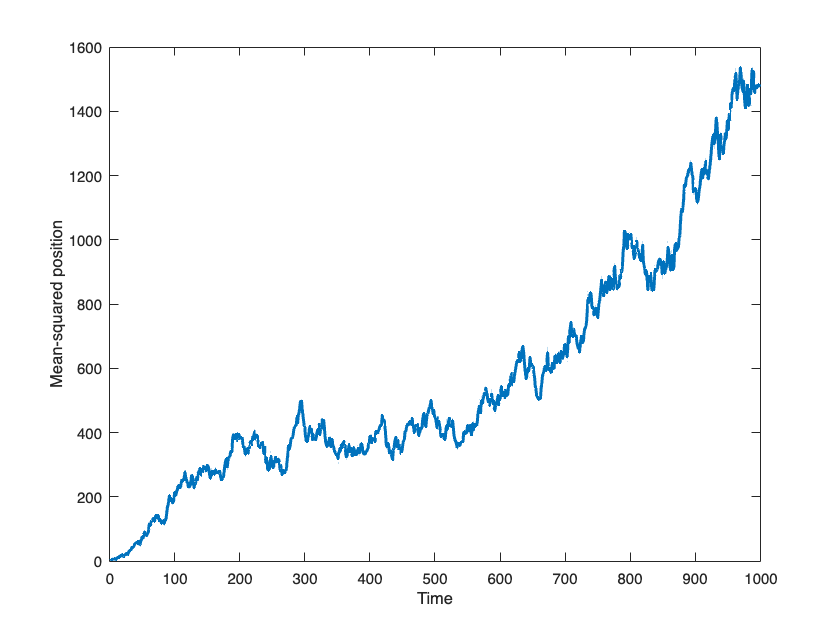

figure;
plot(t,VarX(1,:),'LineWidth',2);         
xlabel('Time');
ylabel('Mean-squared position');

n_traces = 100;
t = 1:1:1000;                    %time
v=randn(length(t), n_traces);         %random velocities(#time points per trace, #traces)
x=cumsum(v);                    %integrate by summing the random velocities to give position
% x=x+5*randn(length(t), n_traces);

## Position histograms

figure;
%h0=histogram(x(1,:));
%hold on;
h1=histogram(x(10,:));              %positions at t=10
hold on;
h2=histogram(x(100,:));             %positions at t=100
hold on;
h3=histogram(x(1000,:));               %positions at t=1000
%h0.Normalization = 'probability';
%h0.BinWidth = 2;
h1.Normalization = 'probability';
h1.BinWidth = 2;
h2.Normalization = 'probability';
h2.BinWidth = 2;
h3.Normalization = 'probability';
h3.BinWidth = 2;
xlabel('Position');
ylabel('Probability density');
PrettyFig; 

## MSD plots

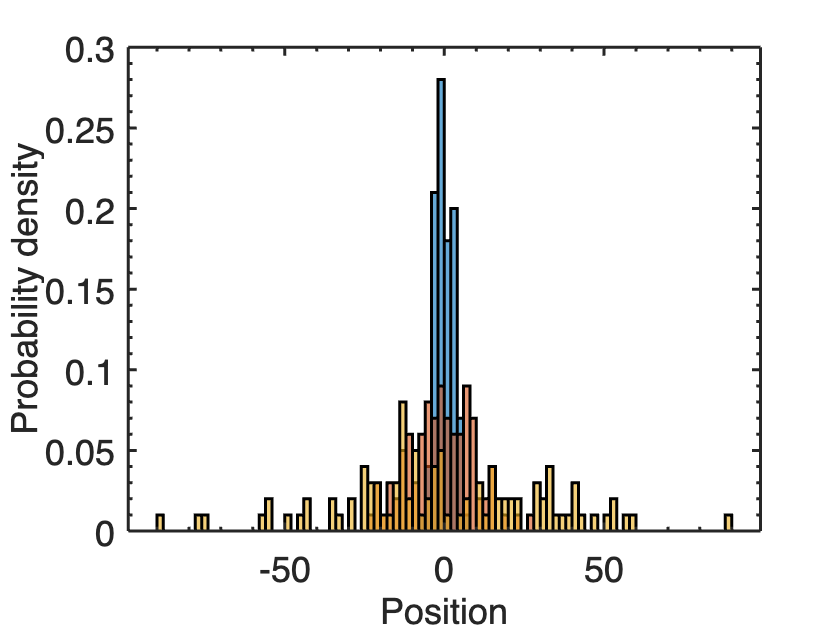

VarX=var(x.');                   %Variance at each time point (note taking transpose of matrx)
PrettyFig;

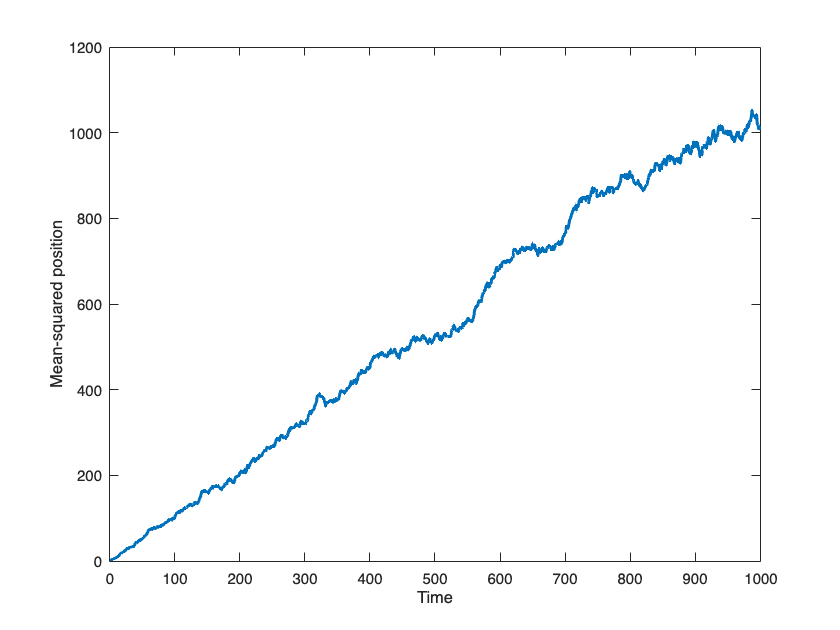

figure;
plot(t,VarX(1,:),'LineWidth',2);         
xlabel('Time');
ylabel('Mean-squared position');

n_traces = 10000;
t = 1:1:1000;                    %time
v=randn(length(t), n_traces);         %random velocities(#time points per trace, #traces)
x=cumsum(v);                    %integrate by summing the random velocities to give position
% x=x+5*randn(length(t), n_traces);

## Position histograms

figure;
%h0=histogram(x(1,:));
%hold on;
h1=histogram(x(10,:));              %positions at t=10
hold on;
h2=histogram(x(100,:));             %positions at t=100
hold on;
h3=histogram(x(1000,:));               %positions at t=1000
%h0.Normalization = 'probability';
%h0.BinWidth = 2;
h1.Normalization = 'probability';
h1.BinWidth = 2;
h2.Normalization = 'probability';
h2.BinWidth = 2;
h3.Normalization = 'probability';
h3.BinWidth = 2;
xlabel('Position');
ylabel('Probability density');
PrettyFig; 

## MSD plots

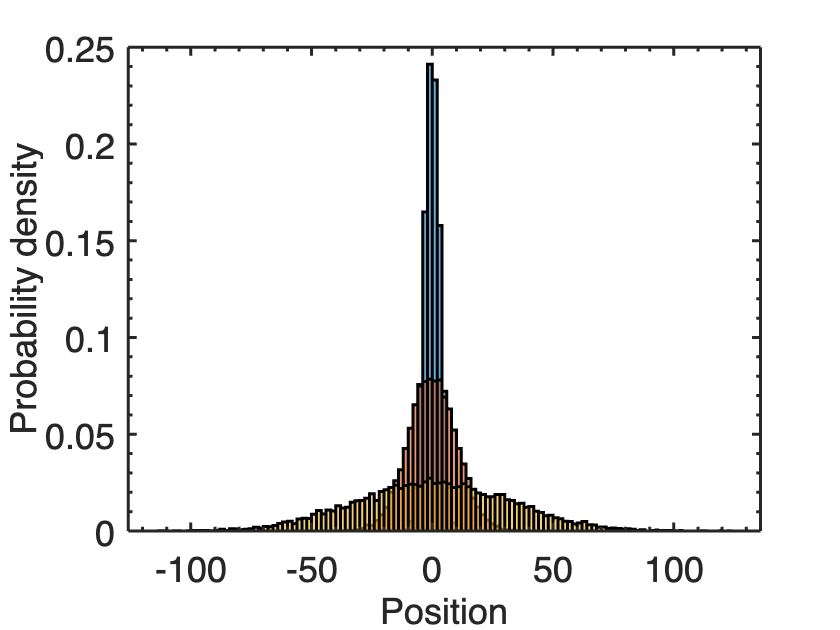

VarX=var(x.');                   %Variance at each time point (note taking transpose of matrx)
PrettyFig;

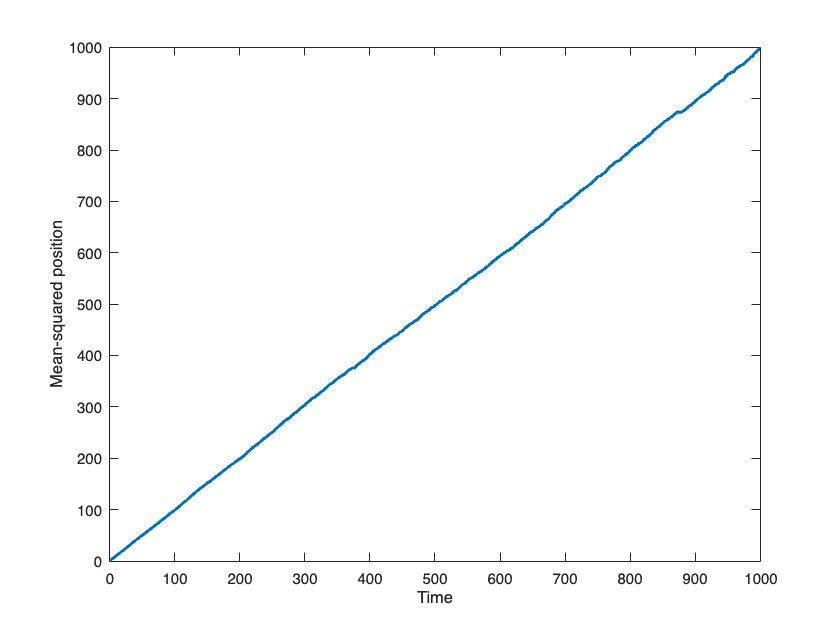

figure;
plot(t,VarX(1,:),'LineWidth',2);         
xlabel('Time');
ylabel('Mean-squared position');

## Question 3.

As the number of traces is increased -- 10, 100, and 10000.

- Displacement histograms show clearer increase in variance as the amount of time the particles are allowed to diffuse; most clearly observable when number of traces is 10000.

- Displacement histograms also show a better centering around zero mean displacement. In fact, this is barely observable when the number of traces is just 10 or 100.

- The MSD curves deviate lesser from a prefectly linear plot.

In general, the greater the number of trials used to simulate the diffusion process, the better he average properties emerge and the statistical estimates become more reliable and agree with the theortical expectations.

## Question 4.

n_traces = 1000;
t = 1:1:1000;                    %time
v=randn(length(t), n_traces);         %random velocities(#time points per trace, #traces)
x=cumsum(v);                    %integrate by summing the random velocities to give position
x=x+10*randn(length(t), n_traces);

## Position histograms

figure;
%h0=histogram(x(1,:));
%hold on;
h1=histogram(x(10,:));              %positions at t=10
hold on;
h2=histogram(x(100,:));             %positions at t=100
hold on;
h3=histogram(x(1000,:));               %positions at t=1000
%h0.Normalization = 'probability';
%h0.BinWidth = 2;
h1.Normalization = 'probability';
h1.BinWidth = 2;
h2.Normalization = 'probability';
h2.BinWidth = 2;
h3.Normalization = 'probability';
h3.BinWidth = 2;
xlabel('Position');
ylabel('Probability density');
PrettyFig; 

## MSD plots

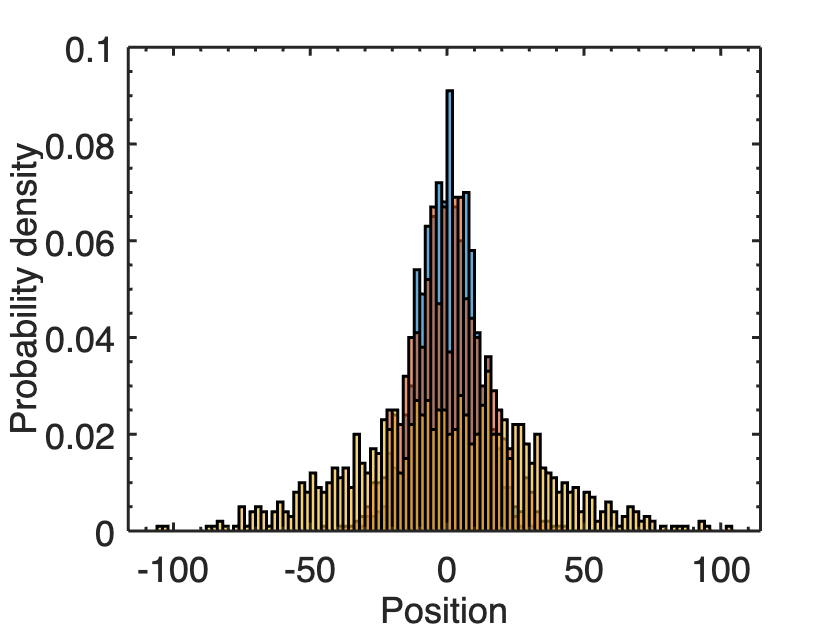

VarX=var(x.');                   %Variance at each time point (note taking transpose of matrx)
PrettyFig;

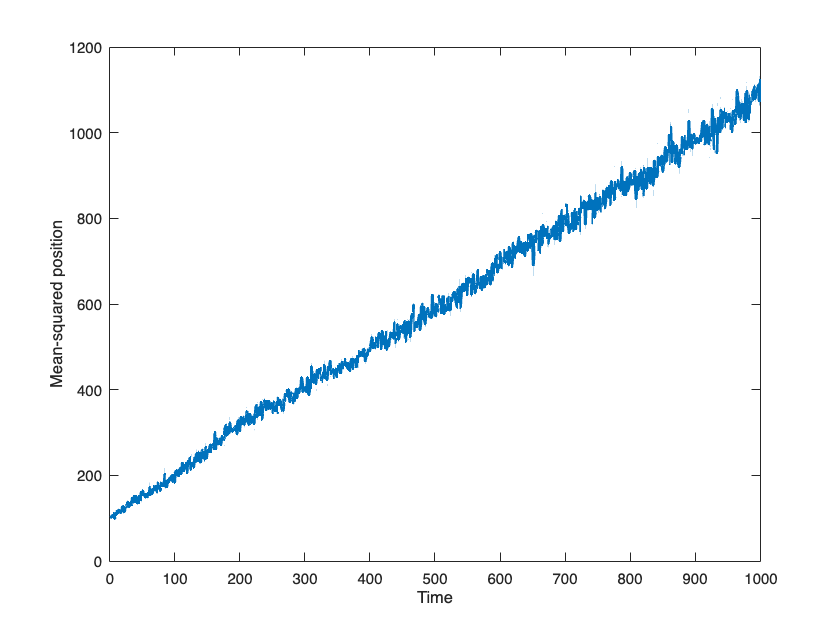

figure;
plot(t,VarX(1,:),'LineWidth',2);         
xlabel('Time');
ylabel('Mean-squared position');

Upon adding measurement noise to the x trace, the MSD plot shifts up the y-axis by 100 distance-squared units since the noise term has an amplitude of 10 distance units. Further, the MSD values fluctuate about the expected MSD plot in both positive and negative directions (i.e., it becomes noisy). The noise becomes higher at later timepoints since more noise has accumulated in the trajectories over time.

The diffusion coefficient can still be estimated by assuming an approximate line through the center of the noisy trajectory; this would be a good approximation since the measurement noise added is drawn from a random normal distribution which, on an average, deviates both positively and negatively from the expected trajectory and still likely follows the expected trace more or less.

Based on the plot above, the diffusion coefficient is **still about 0.5**.